clc; clear; close;

# Expressions de la force de poussée

#### Donneés

R = (12.7/2) * 1e-2;
A = pi * R^2;
rho = 1.225;
M_struct = 3;
RPM = 10000;
propeller_pitch = 10.16 * 1e-2;

#### Script

v_rotor = rotor_speed(RPM, propeller_pitch); % [m/s]
disp("The rotor speed is (for RPM = 10000) : " +  num2str(v_rotor) + " m/s.")

The rotor speed is (for RPM = 10000) : 53.1976 m/s.


v_induced = induced_speed(M_struct, rho, A); % [m/s]
disp("The speed induced by the rotor is : " + num2str(v_induced) + " m/s.")

The speed induced by the rotor is : 30.7938 m/s.


m_dot = mass_flow(rho, A, v_induced); % [kg/s]
disp("The value of mass flow throught the rotor is : " + num2str(m_dot) + " kg/s.")

The value of mass flow throught the rotor is : 0.47786 kg/s.


Thrust_ref = thrust_v_induced(m_dot, v_induced); % [N]
disp("The thrust with this condition it's : " + num2str(Thrust_ref) + " N.")

The thrust with this condition it's : 29.43 N.


C_f = thrust_coeff(Thrust_ref, rho, A, v_rotor);
disp("The thrust coefficient is : " + num2str(C_f) + " .")

The thrust coefficient is : 1.3403 .


T = propeller_thrust(rho, A, v_rotor);
disp("With this condition, the thrust generated by the propeller is : " + num2str(T) + " N.")

With this condition, the thrust generated by the propeller is : 18.8352 N.


#### Plot

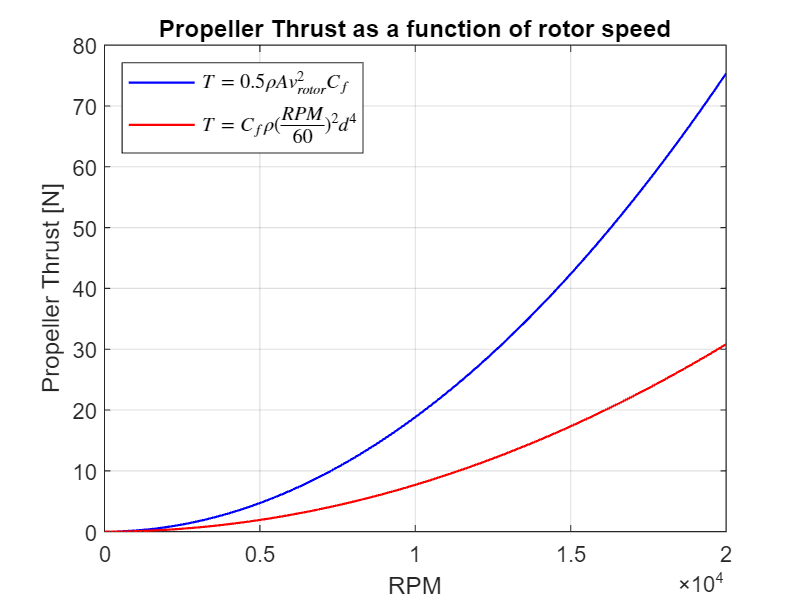

RPM = linspace(0, 20000);
v_rotor = rotor_speed(RPM, propeller_pitch);

T_1 = propeller_thrust(rho, A, v_rotor);
T_2 = 0.87 * rho .* (RPM/60).^2 * (2*R).^4;

figure(1)
plot(RPM, T_1, 'Color', 'b', 'LineWidth', 1);
hold on;
plot(RPM, T_2, 'Color', 'r', 'LineWidth', 1)
xlabel("RPM")
ylabel("Propeller Thrust [N]")
title("Propeller Thrust as a function of rotor speed")
legend('$T = 0.5 \rho A v^{2}_{rotor} C_{f}$', '$T = C_{f} \rho (\frac{RPM}{60})^{2} d^{4}$', 'Interpreter', 'latex', 'Location', 'northwest')
grid on;

#### Fonction

function [v_rotor] = rotor_speed(RPM, R)
    v_rotor = 2 * pi * R/2 * (RPM/60);
end

function [v_induced] = induced_speed(M_struct, rho, A)
    g = 9.81;
    v_induced = sqrt((M_struct * g)/(2 * rho * A));
end

function [m_dot] = mass_flow(rho, A, v_induced)
    m_dot = rho * A *v_induced;
end

function [Thrust_ref] = thrust_v_induced(m_dot, v_induced)
    v_inf = 2 * v_induced;
    Thrust_ref = m_dot * v_inf;
end

function [C_f] = thrust_coeff(Thrust_ref, rho, A, v_rotor)
    C_f = 2 * Thrust_ref / (rho * A * v_rotor^2);
end

function [T] = propeller_thrust(rho, A, v_rotor)
    T = 1/2 * rho * A .* v_rotor.^2 * 0.857792331187080;
end